# Predicción de la GPC

## **1) Importat Datos**

[A, B] = uigetfile({'*xlsx'});
Direccion_Archivo = string(B) + string(A);
Datos = Importar_DRS1(Direccion_Archivo);
Datos = removevars(Datos, 11); % Esta variable se repite

## 2) Evaluación de la influencias de las variables socioeconómicas sobre la generación percápita de residuos

Respuesta = "Generación percápita (Kg/hab/día)";
Variables = string(Datos.Properties.VariableNames);
Ipred = Variables ~= Respuesta;
Variables = Variables(Ipred);
for i = 1 : length(Variables)
    Icat(i) = iscategorical(Datos{1,Variables(i)});
end
Variables_Numericas = Variables(~Icat);
Variables_Numericas = Variables_Numericas([2,6,5,3,4,1]);
Variables_Categoricas = Variables(Icat);

### 2.1) Variables numéricas

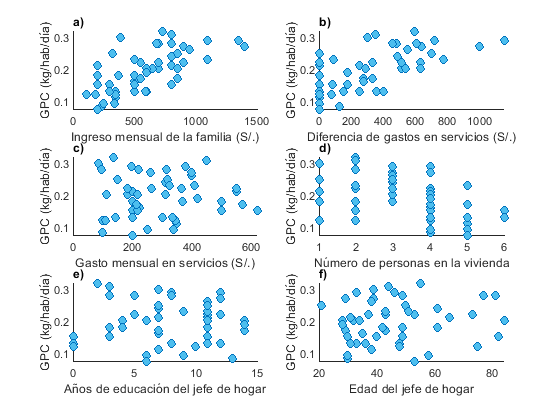

n = length(Variables_Numericas);
alfabeto = 'a' : 'z';
y = Datos.(Respuesta);
Color = [0.301960784313725 0.745098039215686 0.933333333333333];
figure(1)
for i = 1 : n
    subplot(3,2,i)
    x = Datos{:,Variables_Numericas(i)};
    [C(i),p(i)] = corr(x,y,"type","Spearman");
    scatter(x,y,"MarkerFaceColor",Color)
    ttl = title(string(alfabeto(i)) + ")");
    ttl.Units = 'Normalize'; 
    ttl.Position(1) = 0; 
    ttl.HorizontalAlignment = 'left';
    xlabel(Variables_Numericas(i))
    ylabel("GPC (kg/hab/día)")
end

warning off
Umbral_Rho_Spearman = 0.4;
VN = table(Variables_Numericas',C');
VN.Properties.VariableNames{1} = 'Factores';
VN.Properties.VariableNames{2} = 'Estadístico';
VN{abs(VN.("Estadístico"))<Umbral_Rho_Spearman,"Desición"} = "Rechazado";
VN{abs(VN.("Estadístico"))>Umbral_Rho_Spearman,"Desición"} = "Aceptado";
VN

VN = 6×3 table
                    Factores                     Estadístico     Desición  
    _________________________________________    ___________    ___________

    "Ingreso mensual de la familia (S/.)"          0.68271      "Aceptado" 
    "Diferencia de gastos en servicios (S/.)"      0.65428      "Aceptado" 
    "Gasto mensual en servicios (S/.)"            0.064107      "Rechazado"
    "Número de personas en la vivienda"           -0.47805      "Aceptado" 
    "Años de educación del jefe de hogar"          0.07257      "Rechazado"
    "Edad del jefe de hogar"                       0.10405      "Rechazado"


### 2.2) Variables categóricas

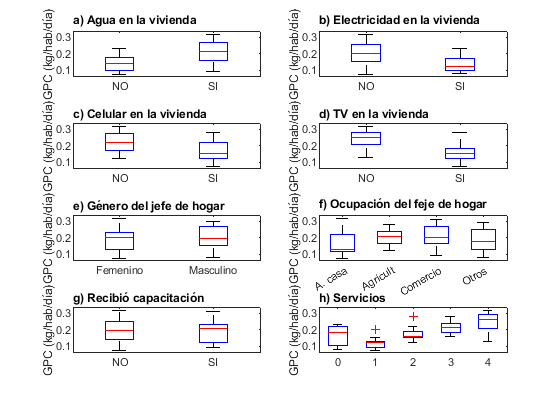

n = length(Variables_Categoricas);
figure(2)
for i = 1 : 8
    subplot(4,2,i)
    x = Datos{:,Variables_Categoricas(i)};
    boxplot(y,x)
    ttl = title(alfabeto(i) + ") " + Variables_Categoricas(i));
    ttl.Units = 'Normalize'; 
    ttl.Position(1) = 0; % use negative values (ie, -0.1) to move further left
    ttl.HorizontalAlignment = 'left';
    ylabel("GPC (kg/hab/día)")
    p_valor(i) = anova1(y,x,"off");
end

Umbral_p_valor = 0.05;
VC = table(Variables_Categoricas',p_valor');
VC.Properties.VariableNames{1} = 'Factores';
VC.Properties.VariableNames{2} = 'Estadístico';
VC{abs(VC.("Estadístico"))<Umbral_p_valor,"Desición"} = "Aceptado";
VC{abs(VC.("Estadístico"))>Umbral_p_valor,"Desición"} = "Rechazado";
VC

VC = 8×3 table
              Factores               Estadístico     Desición  
    _____________________________    ___________    ___________

    "Agua en la vivienda"            0.00063309     "Aceptado" 
    "Electricidad en la vivienda"     0.0099091     "Aceptado" 
    "Celular en la vivienda"          0.0035585     "Aceptado" 
    "TV en la vivienda"              1.7205e-07     "Aceptado" 
    "Género del jefe de hogar"          0.52919     "Rechazado"
    "Ocupación del feje de hogar"       0.29664     "Rechazado"
    "Recibió capacitación"              0.96088     "Rechazado"
    "Servicios"                      2.3316e-06     "Aceptado" 


## 3) Modelación

VarSN = VN.Factores(VN.("Desición") == "Aceptado");
VarCN = VC.Factores(VC.("Desición") == "Aceptado");
cvars = [VarSN;VarCN];

DC = (string(Datos{:,VarCN}));
DC(DC == "SI") = 1;
DC(DC == "NO") = 0;
DC = str2double(DC);
DN = Datos{:,VarSN};
Entrada = [DN,DC];
Entrada = normalize(Entrada,'range');
Salida = y;

rng(1)
[RegrModel, ~] = EntrenRegrModel(Datos);
[RamdFModel, ~] = EntrenRamdFModel(Datos);
[SVMModel, ~] = EntrenSVMModel(Datos);
[ProcGaussModel, ~] = EntrenProcGaussModel(Datos);

RNNModel = EntrenamientoRNN(Entrada,Salida);

Y_RegrModel = RegrModel.predictFcn(Datos);
Y_RamdFModel = RamdFModel.predictFcn(Datos);
Y_SVMModel = SVMModel.predictFcn(Datos);
Y_ProcGaussModel = ProcGaussModel.predictFcn(Datos);
Y_RNNModel = RNNModel(Entrada')';

Titulos = ["Regresión","Random Forest","Support Vector Machine","Procesos Gaussianos","Redes Neuronales"];
Y_Pred = table(Y_RegrModel,Y_RamdFModel,Y_SVMModel,Y_ProcGaussModel,Y_RNNModel);
clear RM
for i = 1 : 5
    RM(i,:) = rMetrics(y,Y_Pred{:,i});
end
RM.Modelos = categorical(Titulos')

RM = 5×5 table
       mae          mse          rmse         Rsq             Modelos        
    _________    __________    _________    _______    ______________________

     0.011109    0.00017903      0.01338    0.95856    Regresión             
     0.021963    0.00072781     0.026978    0.83156    Random Forest         
    0.0072333    5.9832e-05    0.0077351    0.98615    Support Vector Machine
    0.0073483    7.7115e-05    0.0087815    0.98215    Procesos Gaussianos   
      0.01128    0.00025193     0.015872    0.94169    Redes Neuronales      


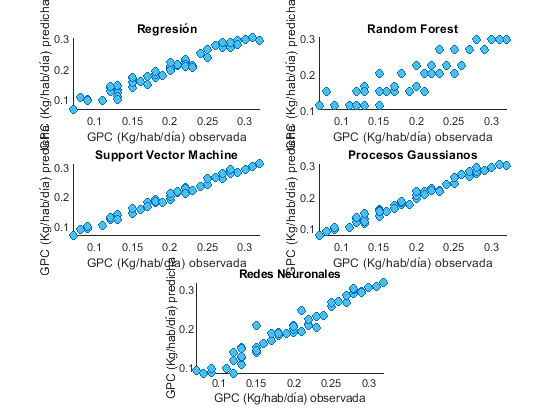

figure
for i = 1 : 4
    h(i) = subplot(3,2,i);
    scatter(y,Y_Pred{:,i},'MarkerFaceColor',Color)
    title(Titulos(i))
    xlabel("GPC (Kg/hab/día) observada")
    ylabel("GPC (Kg/hab/día) predicha")
end
h(5) = subplot(3,2,5); % the last (odd) axes
pos = get(h,'Position');
new = mean(cellfun(@(v)v(1),pos(1:2)));
set(h(5),'Position',[new,pos{end}(2:end)])
scatter(y,Y_Pred{:,5},'MarkerFaceColor',Color)
title(Titulos(5))
xlabel("GPC (Kg/hab/día) observada")
ylabel("GPC (Kg/hab/día) predicha")

[A,B] = uiputfile('*.xlsx');
Ruta_Guardado = string(B) + string(A);
writetable(Ruta_Guardado)